    "Phase: "    "0"



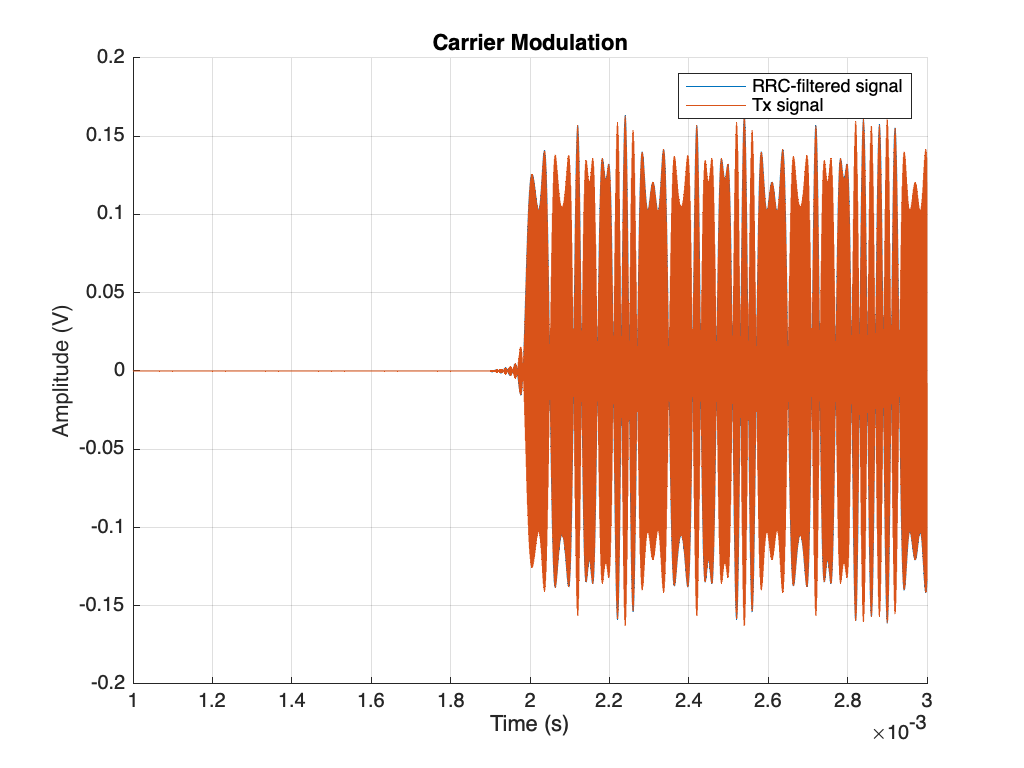

clear;
close all;

constants.data_bits = [0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 1 1 0 0 1 1 1 0 1,...
    1 1 0 0 1 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 1 0 0 1 1 0 0 1 0,...
    0 0 0 1 0 0 1 0 0 0 0 0 0 1 0 1 0 0 1 1 0 1 1 0 1 0 0 1 0 1 1 0 1 1,...
    0 1 0 1 1 1 0 1 0 1 0 1 1 0 1 1 0 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0,...
    0 1 1 0 1 0 0 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 0 1 0 0 0 0 0 0 1,...
    1 0 1 0 0 1 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 0 0 1 1 0 0 0 1 1 0 1 1 0,...
    1 1 1 1 0 1 1 0 1 1 0 1 0 1 1 1 0 0 0 0 0 1 1 0 1 1 0 0 0 1 1 0 0 1,...
    0 1 0 1 1 1 0 1 0 0 0 1 1 0 0 1 0 1]; % "..." is line continuation
constants.noise_std_dev =0.001;

% Values that we're giving you
constants.Fs = 4e6; % Sampling rate (samples/sec)
constants.Rs = 50e3; % Symbol rate in symbols/sec (baud)
constants.Tmax = 0.1; % Max time for the simulation (sec)
constants.fc = 1e6; % Carrier frequency (Hz)
constants.B = 350e3; % Bandwidth (Hz)

% Complete these expressions using the variables above
constants.N = constants.Fs*constants.Tmax; % Total number of sample points in the simulation
constants.Ns = constants.Rs*constants.Tmax; % Number of symbols to send
constants.sps = constants.Fs/constants.Rs; % Number of samples per symbol

constants.t = linspace(0, constants.Tmax-1/constants.Fs, constants.N); % Time vector
constants.f = linspace(-constants.Fs/2, constants.Fs/2, constants.N); % Frequency vector. Recall from 113 that DFT gives us -f/2 to +f/2
constants.key = [1, 1, 1, -1, -1, -1, 1, -1, -1, 1, 1, -1, 1, -1, 1];

[tx_sig, rx_apriori] = run_tx_sim(constants);

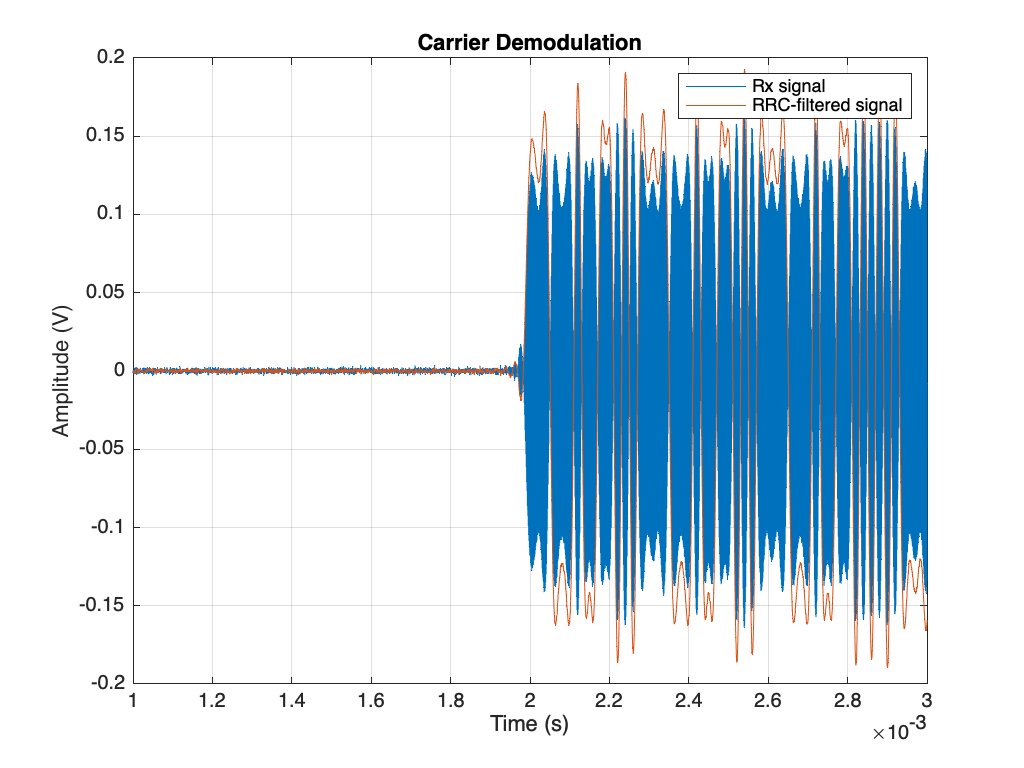

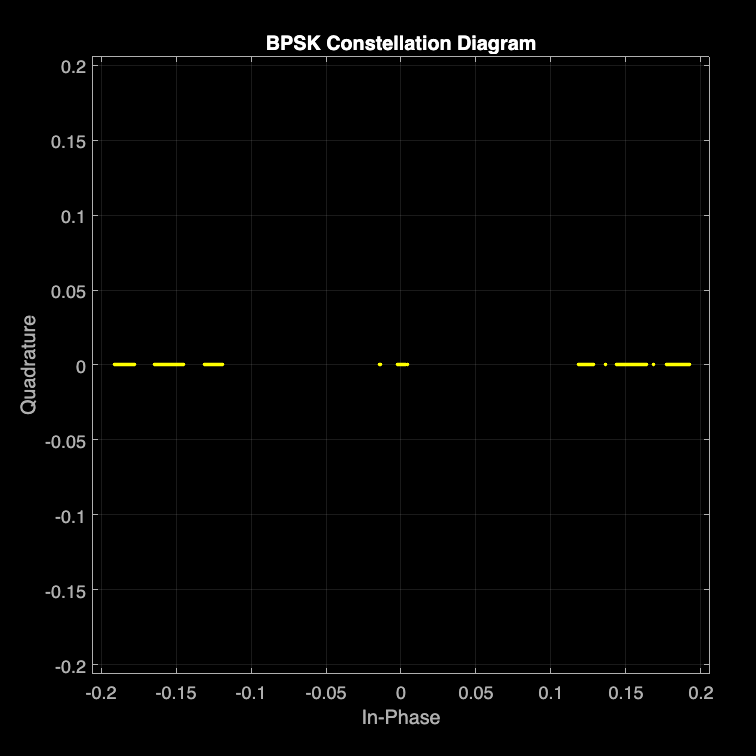

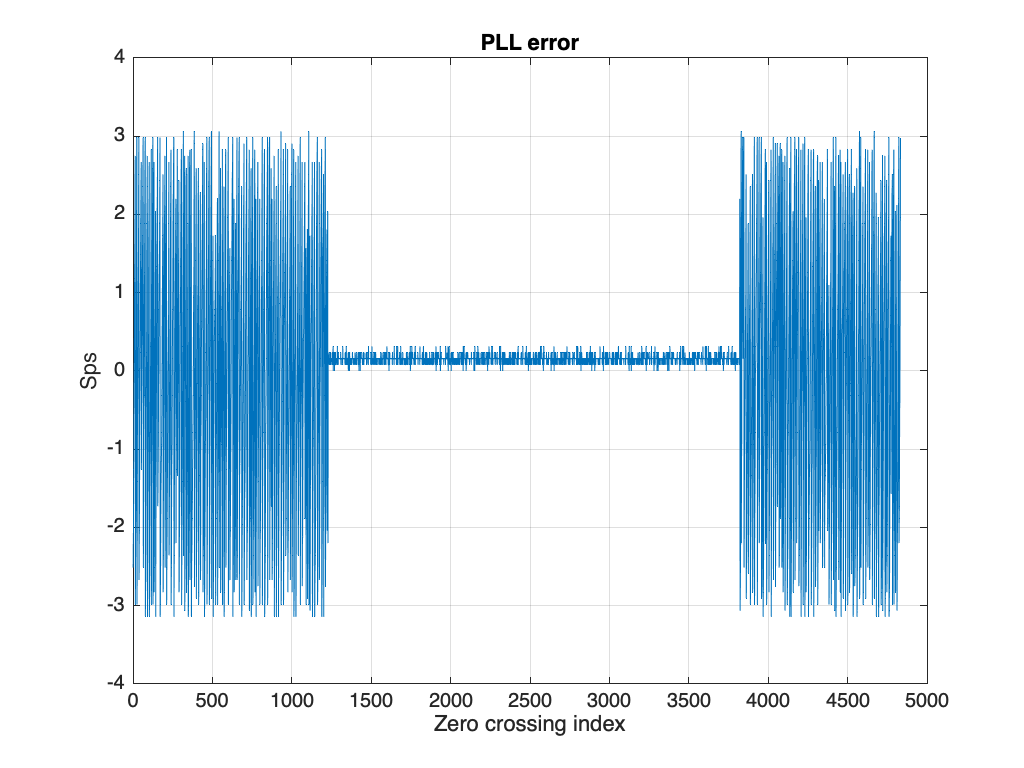

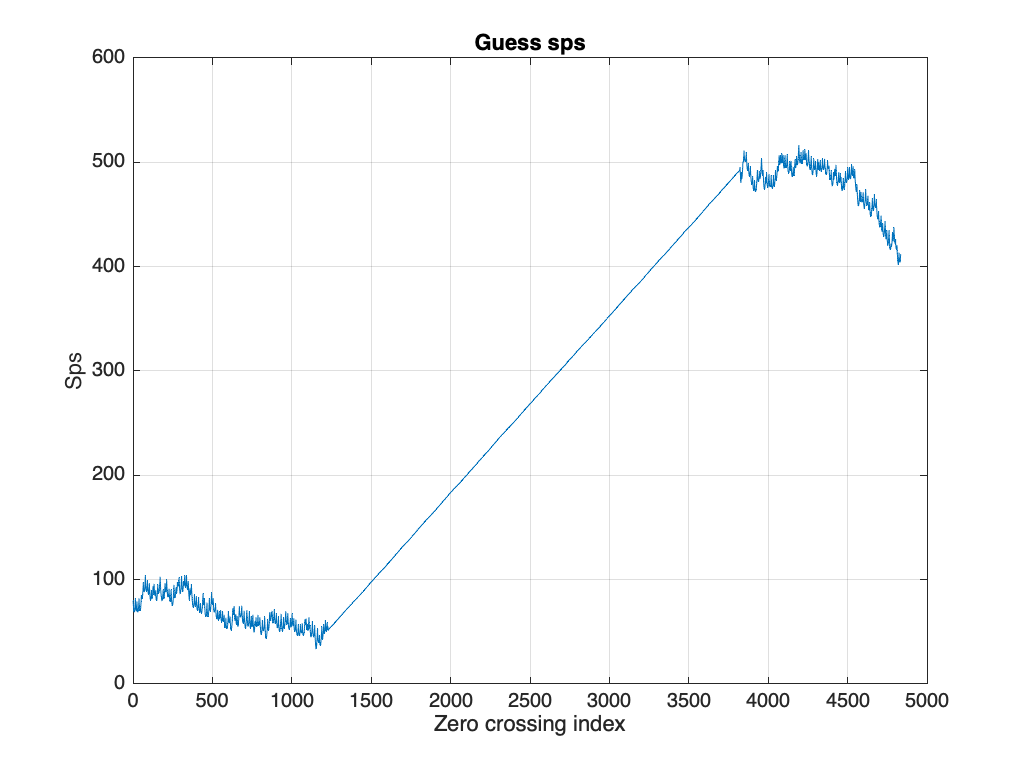

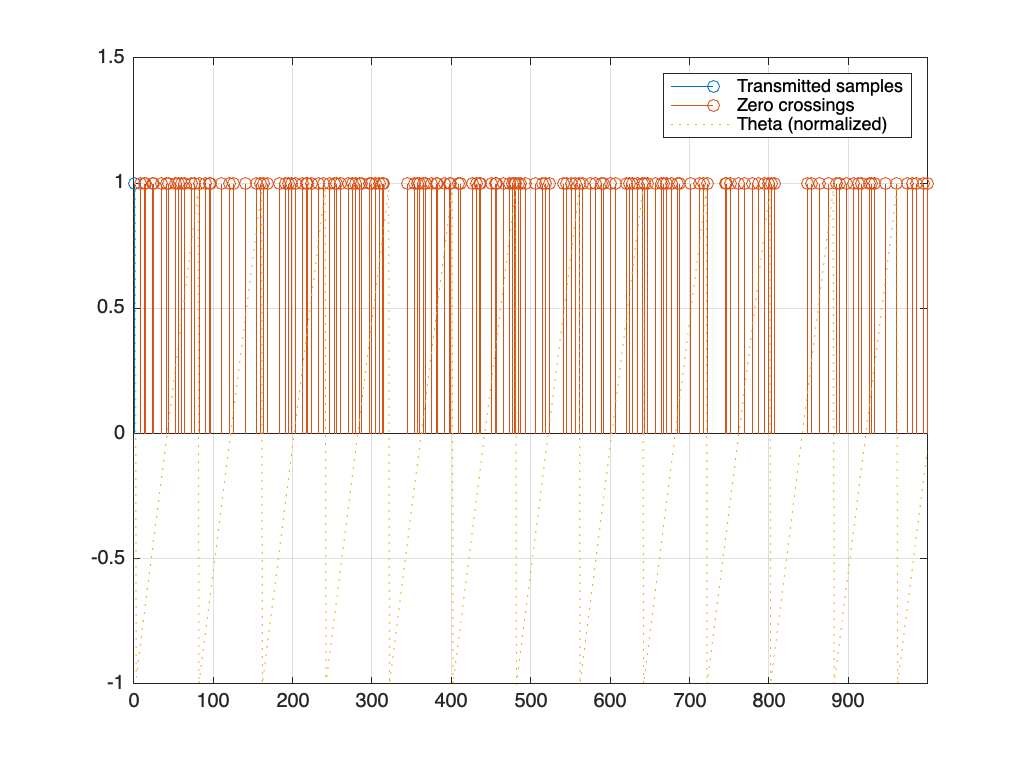

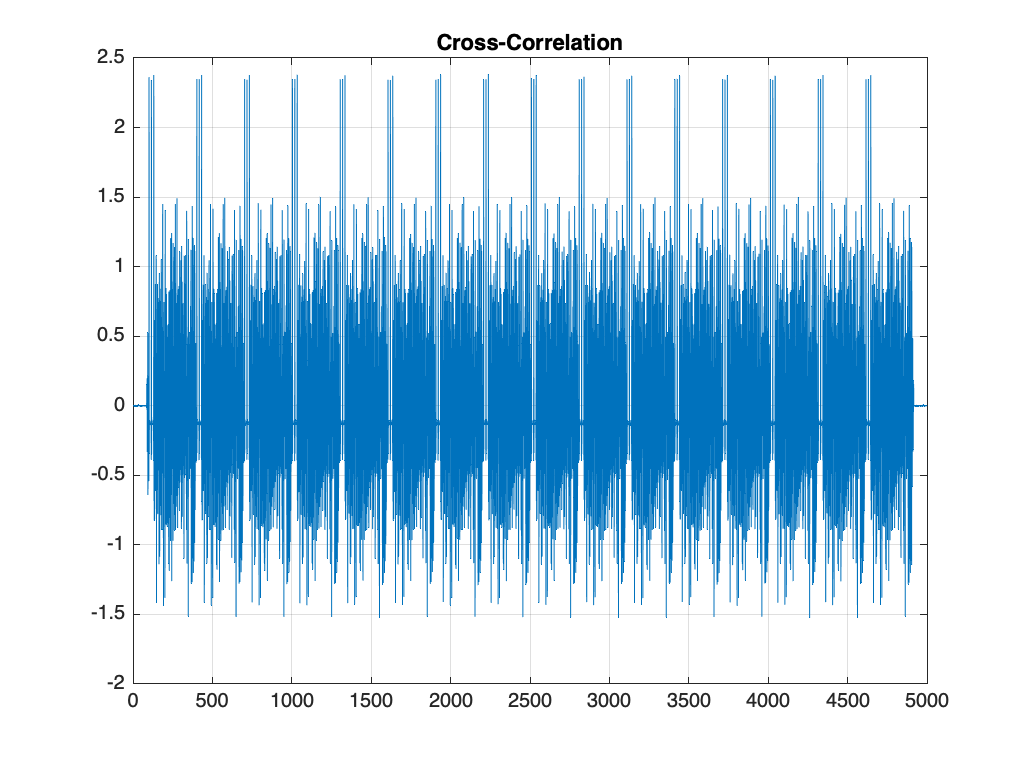

   101



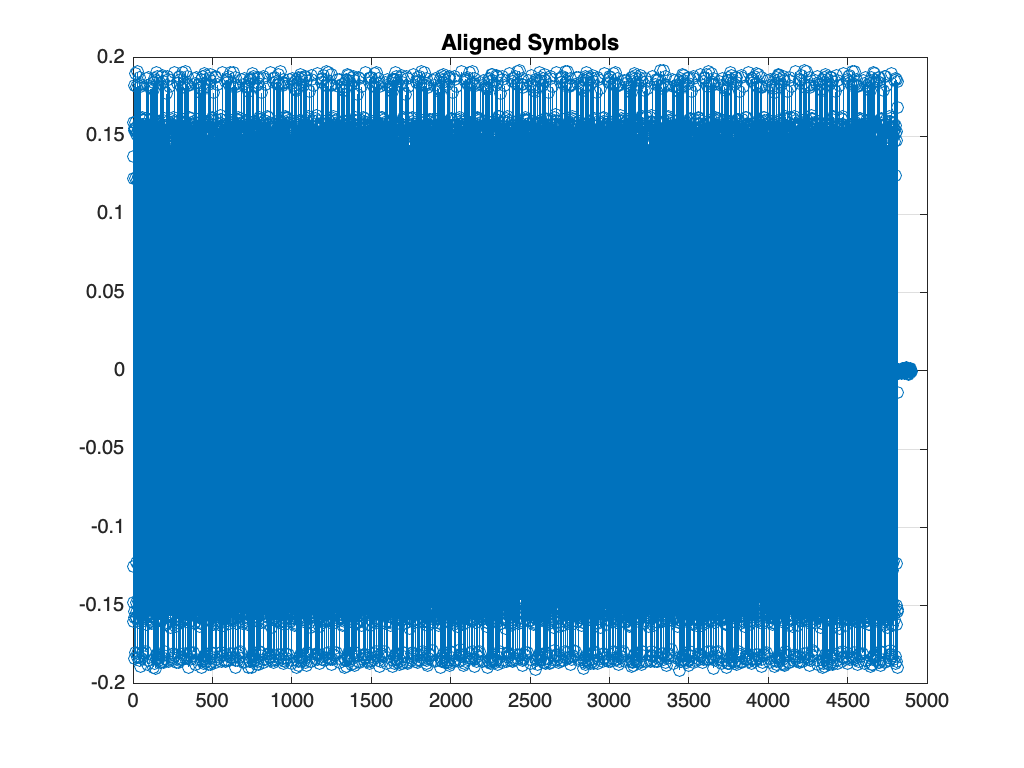

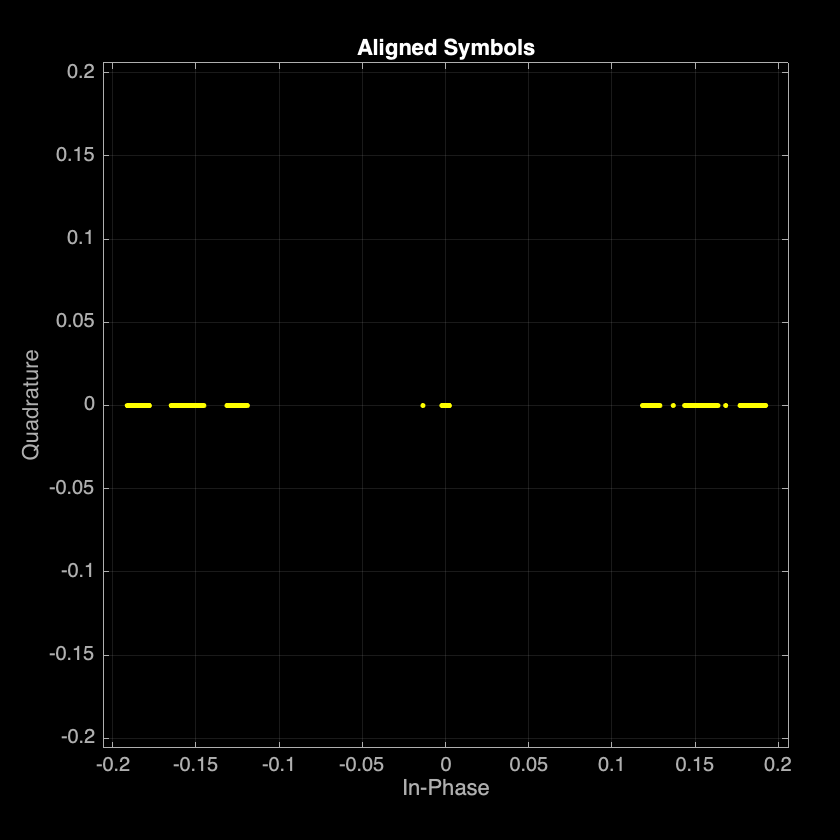

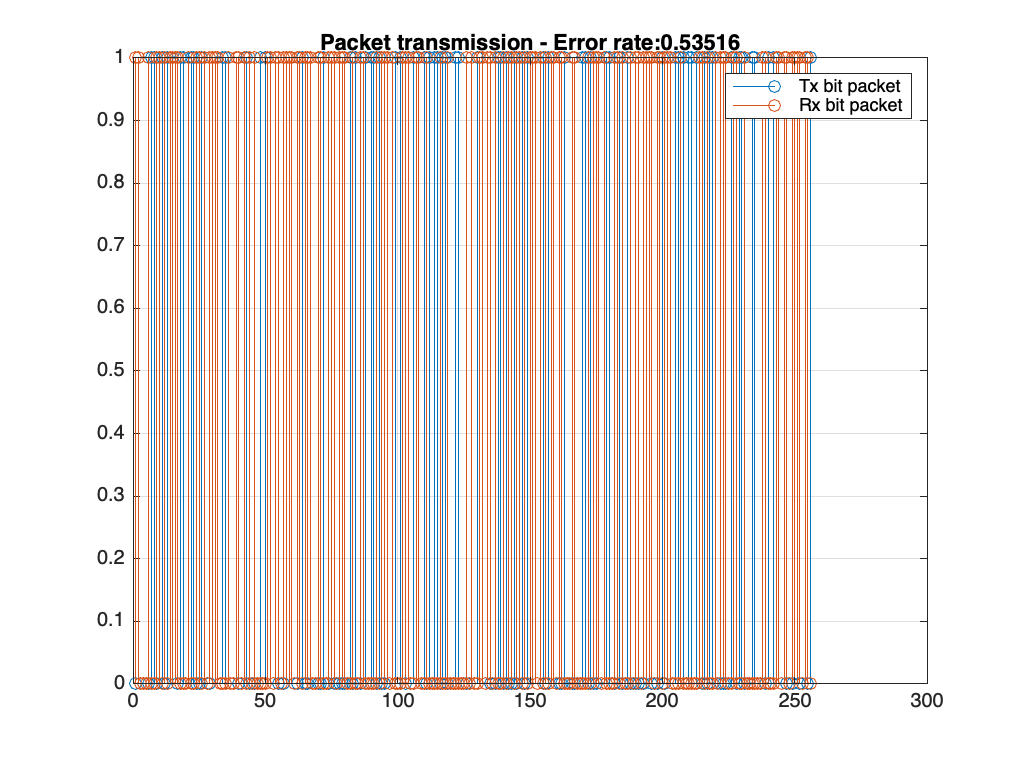

1 1 0 0 0 1 0 0 1 1 0 1 0 1 1 1 1 0 0 0 1 0 0 1 1 0 1 0 1 1 1 1 0 0 0 1 0 0 1 1 0 1 0 1 0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 1 1 0 0 1 1 1 0 1 1 1 0 0 1 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 1 0 0 1 0 0 0 0 0 0 1 0 1 0 0 1 1 0 1 1 0 1 0 0 1 0 1 1 0 1 1 0 1 0 1 1 1 0 1 0 1 0 1 1 0 1 1 0 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 0 1 0 0 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 0 1 0 0 0 0 0 0 1 1 0 1 0 0 1 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 0 0 1 1 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 0 1 0 1 1 1 0 0 0 0 0 1 1 0 1 1 0 0 0 1 1 0 0 1 0 1 0 1 1 1 0 1 0 0 0 1 1 0 0 1 0 1 1 1 1 0 0 0 1 0 0 1 1 0 1 0 1 1 1 1 0 0 0 1 0 0 1 1 0 1 0 1 1 1 1 0 0 0 1 0 0 1 1 0 1 0 1 0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 1 1 0 0 1 1 1 0 1 1 1 0 0 1 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 1 0 0 1 0 0 0 0 0 0 1 0 1 0 0 1 1 0 1 1 0 1 0 0 1 0 1 1 0 1 1 0 1 0 1 1 1 0 1 0 1 0 1 1 0 1 1 0 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 0 1 0 0 1 0 1 1 0 1 1 1 1 0 1 1 

rec_sig = run_channel_sim(tx_sig, constants.noise_std_dev, constants.N, "NONE");
rec_data_bits = run_rx_sim(rec_sig, rx_apriori, constants);